# Chapter 02 - Algorithm Design in MATLAB.

Authors: Ken Deeley, [ken.deeley@mathworks.co.uk](mailto:ken.deeley@mathworks.co.uk), 

              Louise Brown, [louise.brown@nottingham.ac.uk](http://louise.brown@nottingham.ac.uk)

This chapter provides the necessary programming techniques for algorithm design and development using MATLAB. The idea is that we are now happy writing scripts to organise and collect sequences of MATLAB commands, but these become increasingly difficult to manage as the complexity of our algorithms grows. Moreover, a common requirement is to run scripts repeatedly using different values for certain parameters within the script. Functions are a more effective programming construct for managing these issues. In this chapter we will learn how to develop and structure an algorithm for performing simple preprocessing, model fitting and visualisation. The important concept here is how to modularise code so that it becomes reusable, maintainable, flexible and robust.

Outline:

- Formulating an algorithm for 1D model fitting

- Linear regression models

- Visualising the results

- Generalising the algorithm to 2D model fitting

- Anonymous function handles

- Surface plots

- Code modularisation: from scripts to functions

- Local functions

- Nested functions

- Code robustness and flexibility

- Parsing user-supplied input arguments

- Defining flexible interfaces

- Errors and error identifiers

Reference files for this chapter:

- ../Reference/S02_Algorithm.m

- ../Reference/F02_fitQuadModel.m

- ../Reference/S02_MedData.mat

## Linear Regression Models.

The main example in this chapter is developing an algorithm to perform data preprocessing, fitting and visualisation. We will use a linear regression model with variables chosen from the biomedical data discussed in the first chapter of the course. The examples are fairly simple, but if attendees are unfamiliar with regression, the concepts can be explained in terms of inputs and outputs. For example, we have an input variable (e.g. Age) and we would like to model the dependency of an output variable (e.g. PulsePressure) on the input. It's easier to gather the commands in these sections into a single script, which can then be run section by section and then eventually converted into a properly structured function by the end of the chapter.

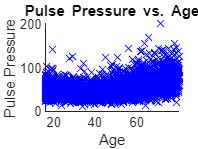

% Visualise the dependency of pulse pressure on age.
load('S02_MedData.mat')
x = MedData.Age;
y = MedData.BPDiff;
figure
scatter(x, y, 'bx')
xlabel('Age')
ylabel('Pulse Pressure')
title('\bfPulse Pressure vs. Age')

*Note that \b is Tex markup in the title for bold.*

This dependency looks as if it could be modelled using a quadratic curve (i.e. using a model of the form PP ~ C0 + C1*Age + C2*Age.^2, where the coefficients C0, C1 and C2 are unknown and to be determined).

## Matrix Equations. 

*Linear regression and matrix equations slides.*

Formulating a linear regression model leads to a system of linear equations A*x = b for the unknown vector of coefficients x. The design matrix A comprises the model terms, and the vector b is the data to be modelled (in this example, the vector of pulse pressure observations). Note carefully that solving such linear systems is a matrix operation, and so any missing values contained in the data must be dealt with in some way before attempting to solve the system. (High-level functionality in Statistics Toolbox can remove missing observations automatically before fitting, but here we use a core MATLAB solution.)

% Clean the data
missingIdx = isnan(x) | isnan(y);
xClean = x(~missingIdx);
yClean = y(~missingIdx);

% Set up the system of equations for fitting a model to the pulse pressure
% data.
designMat = [ones(size(xClean)), xClean, xClean.^2];

## Slash and Backslash.

The least-squares solution of the system A*x = b in MATLAB is given by x = A\b. If the system is formulated as x*A = b, then its solution is x = b/A. 

% Solve the linear system to find the best-fit coefficients for modelling
% pulse pressure as a quadratic function of age.
modelCoeffs = designMat\yClean;


% Compute the fitted model.
pulseModel = designMat*modelCoeffs;

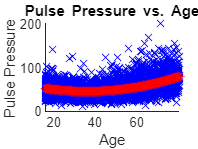


% Visualise the results.
hold on
plot(xClean, pulseModel, 'r*')
hold off

## Matrix and Array Operators.

Note that in the above computations we have used the operators * and \. A complete list of matrix, array and logical operators is available by entering the command >> doc ops.

*It's useful to show this list at this point to point people in the right direction for discovering matrix and array operators.*

doc ops

## Generalising the Model.

We now have an algorithm for fitting a one-dimensional quadratic model to our data. We would like to generalise this to fit a two-dimensional quadratic surface to a single response variable given two input variables. For example, we might be interested in predicting a person's weight given knowledge of their height and waist measurements. We will follow similar steps to preprocess and clean the data before fitting.

% Extract input variables.
x1 = MedData.Height;
x2 = MedData.Waist;

% Extract output variable.
y = MedData.Weight;

% Clean the data.
missingIdx = isnan(x1) | isnan(x2) | isnan(y);
x1Clean = x1(~missingIdx);
x2Clean = x2(~missingIdx);
yClean = y(~missingIdx);

% Formulate the system of linear equations.
designMat = [ones(size(x1Clean)), x1Clean, x2Clean, x1Clean.^2, ...
             x2Clean.^2, x1Clean.*x2Clean];

% Solve the system.                 
modelCoeffs = designMat\yClean;

## Function Handles.

Now that we have the second set of model coefficients for the 2D quadratic model, we would like to visualise the fitted results. To do this, we need to substitute the model coefficients into the model equation. One way to achieve this is to use a function handle, which is a variable containing a reference to a function. Using a function handle reduces the problem of calling a function to that of accessing a variable. The function handle contains all information necessary to evaluate the function at given input arguments. For further information on function handles, see MATLAB -> Language Fundamentals -> Data Types -> Function Handles.

*Show slide on function handles and Anonymous Functions*

% Set up anonymous function for 2D quadratic model equation
modelFun = @(c, x1, x2) c(1) + c(2)*x1 + c(3)*x2 + c(4)*x1.^2 + ...
                        c(5)*x2.^2 + c(6)*x1.*x2;

It's helpful to draw the analogy with the mathematical notation:

f(c, x1, x2) = c(1) + c(2)*x1 + c(3)*x2 + c(4)*x1.^2 + c(5)*x2.^2 + c(6)*x1.*x2

The only difference between the mathematical notation and the function handle definition is the "@" symbol, signifying to MATLAB that a function handle is being created.

This function handle can now be evaluated at any point or any series of points, just like a normal mathematical function. For example:

% Evaluate the model function at (0,0).
disp(modelFun(modelCoeffs, 0, 0)) 

   11.6610



## Creating Equally-Spaced Vectors.

At this point, we are ready to visualise our quadratic surface. In MATLAB, surface plots can be created using a fairly straightforward step-by-step procedure. The first step of this process is to create equally-spaced vectors of points of "x" and "y" data (the data forming the horizontal plane). To achieve this, we could use either the colon operator (:) or the LINSPACE function.

% Set up equally-spaced vectors for x and y data with 100 elements
x1Vec = linspace(min(x1Clean), max(x1Clean));
x2Vec = linspace(min(x2Clean), max(x2Clean)); 

Note that 100 points in the vector is the default. The number of points is optional and can be specified as the third input argument to LINSPACE.

## Making Grids.

The second step in the procedure is to create matrices containing the coordinates of all grid points in the lattice. This can be achieved using MESHGRID.

% Create matrices containing grid point coordinates
[X1Grid, X2Grid] = meshgrid(x1Vec, x2Vec);
% X1Grid contains all the "x" coordinates of all the lattice points.
% X2Grid contains all the "y" coordinates of all the lattice points.

Now that we have all lattice points, our surface function can be evaluated over the lattice using the function handle defined above.

% Evaluate surface function over the lattice
YGrid = modelFun(modelCoeffs, X1Grid, X2Grid);

## Surface Plots.

Finally, we can visualise the surface. The basic function here is SURF, into which we provide the three matrices of surface data (the two coordinate matrices and the values of the surface function over the lattice).

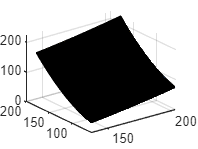

% Visualise the surface
figure; 
surf(X1Grid, X2Grid, YGrid)

 We can customise this display by specifying name-value pairs.

*Show help 'surf' to show property pairs*

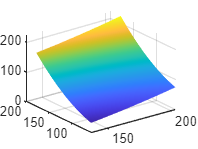

surf(X1Grid, X2Grid, YGrid, 'FaceColor', 'interp', 'EdgeAlpha', 0)

This removes gridlines and uses interpolated shading for the surface, instead of colouring each patch a uniform colour.

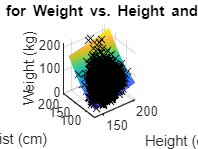

% View the original data.
hold on
plot3(x1Clean, x2Clean, yClean, 'kx')
xlabel('Height (cm)')
ylabel('Waist (cm)')
zlabel('Weight (kg)')
title('\bfModel for Weight vs. Height and Waist')

Other 3D visualisation functions can be found in the Plot Gallery.

## Creating a Function.

At this point, we now have a script which we can run to perform our data clean-up, model fitting and visualisation. However, it is not straightforward to apply the algorithms in our script to another set of data. The next step in modularising our code is to create a function to automate the tasks or subtasks represented in our current script. Functions are created in text files with the .m extension, just like script files. However, functions must begin with a function declaration of the form: function [out1, out2, ...] = function_name(in1, in2, ...) The keyword "function" must be the first non-comment code in the file. Syntax for calling user-defined functions is identical to that used for calling existing MATLAB functions.

*Show creating a new function and live function using New ->*

Open function "fitQuadModel" and add the following declaration line:

function [modelCoeffs, fh] = fitQuadModel(X, y, showplot)

*See the file F02_fitQuadModel_001.*

## Workspaces.

Functions operate within their own function workspace, which is separate from the base workspace accessed at the prompt or from within scripts. If a function calls another function, each maintains its own separate workspace. Once a function has completed, its workspace is destroyed. 

*Instructors may wish to demonstrate the concept of separate workspaces by setting breakpoints and entering debug mode. *

*Demonstrate with foo.m - call from command line with 'val = foo(pi)'*

*Also a = 24, b = foo(a);*

*Variables are passed by value.*

## Local Functions.

There may be times when we wish to outsource certain tasks in a function to another function. For example, if we think about our algorithm at a high-level, we are performing three distinct tasks: * we are cleaning up the data by removing NaNs; * we are performing the model fitting; * we are visualising the results of the fitted model.

We are performing these three tasks on two distinct sets of data. One possibility for structuring our main function is to have three local functions defined inside, each of which represents one of the three tasks above. This enables us to reuse the same function for multiple different sets of data.

*Recommended activity: write separate local functions removeNaNs, fitModel and visualiseResults inside the main fitQuadModel function file.*

*See the file F02_fitQuadModel_002.*

%end % main function fitQuadModel

%function [XClean, yClean] = removeNaNs(X, y)   
        
%end % removeNaNs

%function modelCoeffs = fitModel(XClean, yClean)    
        
%end % fitModel

%function fh = visualiseResults(X, y, XClean, modelCoeffs)
    
%end % visualiseResults


Next, start to move the code from the script into the appropriate places in the function. We will need to deal with the cases of 1D data and 2D separately, although some code is appropriate for both cases.

*See the file F02_fitQuadModel_003.*

*First add pseudocode in main function for function calls*

% Clean the data.
% Fit the model.
% Visualise the results.

*Add code for ****clean data function**** - ****lines 11-13   Change x to X***

*Will this work if x has two columns?  Use the 'any' function to deal with X matrix having 2 columns. *

***any****    True if any element of a vector is a nonzero number or is*

*    logical 1 (TRUE).*

***any(X,DIM)**** operates down the dimension DIM of an array X. So any( X, 2) operates on 2nd dimension, colums*

missingIdx = isnan(y) | any(isnan(X), 2);

*Then change XClean so works with all columns:*

XClean = X(~missingIdx, :);

***Add to fitModel function:***

*First create design matrix - ****line 16  Change x to X***

*Again, will it work for X with two columns?  ****lines 41-42 for quad***

*Need to separate columns:*

% x1 = XClean(:, 1); 
% x2 = XClean(:, 2);
% designMat = [ones(size(x1)), x1, x2, x1.^2, x2.^2, x1.*x2];

*How do we get the function to carry out the correct designMat formulation?*

*Find the size of X in dimension 2 and then switch:*

% n = size(XClean, 2);
    
%    switch n
%        case 1
%            designMat = [ones(size(XClean)), XClean, XClean.^2];
%        case 2
%            x1 = XClean(:, 1); x2 = XClean(:, 2);
%            designMat = [ones(size(x1)), x1, x2, x1.^2, x2.^2, x1.*x2];
%    end % switch/case

*Then calculate the coefficients - ****line 45****:*

% modelCoeffs = designMat\yClean;

*Finally, visualise the results.*

*Again, will need case for X with 1 and 2 columns, so get size, create figure and add switch:*

% n = size(XClean, 2);
% fh = figure;
%switch n
%     case 1
%     case 2  
% end

*Take the model function for quad from ****lines 47-48 ****and create new one for case 1*

% modelFun = @(c, x) c(1) + c(2)*x + c(3)*x.^2;

*Scatter plot from ****line 6 ****and visualise from ****lines 25-27, ****substituting use of modelFun instead of pulseModel:*

% scatter(x, y, 'bx')
% hold on
% plot(xClean, modelFun(modelCoeffs, XClean, 'r*')
% hold off

*For quad model, create scatter plot of original data:*

% scatter3(X(:,1), X(:,2), y, 'kx')

*Remind about creating equally-spaced grids and mesh data then:*

% hold on
% x1Vec = linspace(min(XClean(:,1)), max(XClean(:,1)));
% x2Vec = linspace(min(XClean(:,2)), max(XClean(:,2)));
% [X1Grid, X2Grid] = meshgrid(x1Vec, x2Vec);
% YGrid = modelFun(modelCoeffs, X1Grid, X2Grid);
% surf(X1Grid, X2Grid, YGrid, 'FaceColor', 'interp', 'EdgeAlpha', 0)
% hold off

*Finally we add the calls to the functions in the main function:*

% [XClean, yClean] = removeNaNs(X, y);
% modelCoeffs = fitModel(XClean, yClean);

*Need to think about that last parameter - showplot - how do we decide whether or not to plot the data?*

%if showplot
%        fh = visualiseResults(X, y, XClean, modelCoeffs);
%    else
%        fh = [];
%    end % if

When the functions have been set up we can test them for both use cases, where X has either one or two columns.

*Clear workspace first*

% Clear workspace and reload medData
load('S02_MedData.mat') 

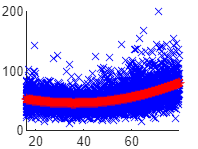

modelCoeffs =    68.0102
   -1.2446
    0.0174


fh1 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [403 246 560 420]
       Units: 'pixels'

  Show all properties


% Set up Age and BPDiff data and call function to run model
x = MedData.Age;
y = MedData.BPDiff;
[modelCoeffs, fh1] = fitQuadModel(x,y,true)

Quadratic surface example

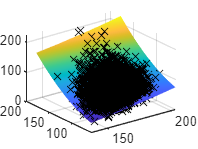

modelCoeffs =    11.6610
   -0.2589
   -0.2360
    0.0024
    0.0059
    0.0005


fh2 =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [1 1 1]
    Position: [403 246 560 420]
       Units: 'pixels'

  Show all properties


% Extract input variables.
X = [MedData.Height MedData.Waist];

% Extract output variable.
y = MedData.Weight;
[modelCoeffs, fh2] = fitQuadModel(X, y, true)

Test without visualisation

[modelCoeffs, fh2] = fitQuadModel(X, y, false)

modelCoeffs =    11.6610
   -0.2589
   -0.2360
    0.0024
    0.0059
    0.0005



fh2 =

     []



## Defining Flexible Interfaces.

As we have written it, the fitQuadModel function requires three inputs, the X data, the y data, and a logical flag indicating whether or not the data should be plotted. MATLAB will return an error message unless exactly three inputs are provided whenever fitQuadModel is called. We can use the NARGIN function to determine how many input arguments were provided when the function was called. With this information, we can set default input values if necessary.

*Show fitQuadModel(x,y)*

We can allow some flexibility for the end user by making the showplot input argument optional (set its default value to false, for example). Inside the body of a user-defined function, **nargin** returns the number of input arguments that were used to call the function.

*See the file F02_fitQuadModel_004.*

% if nargin < 3,  showplot = false; end

*Is this robust? Show what happens with fitQuadModel(x, false)*

## Checking Input Arguments.

Error conditions often arise because run-time values violate certain implicit assumptions made in code. When designing algorithms, especially those that will be used by others, it is important to catch any user-introduced errors. These may not become apparent until later on in the code. In a weakly-typed language such as MATLAB, checking types and attributes of user-supplied input data is particularly important. Recommended approaches include using the family of is* functions (see doc is*) and the more sophisticated function VALIDATEATTRIBUTES.

What assumptions have we made about the X, y and showplot input arguments in our fitQuadModel function?

*Too many | too few arguments*

*X and y are real, non-empty*

*X is 2d matrix*

*y is column*

*showplot  is logical and/or scalar*

*See the file F02_fitQuadModel_005.*

We can use VALIDATEATTRIBUTES and if-statements to respond to errors introduced by users and provide meaningful feedback. At the end of this activity we should have a correct, robust functional interface. Also check that we have between 2 and 3 input arguments using NARGINCHK.

% narginchk(2, 3) % Throws error if nargin is less than low or > high

% validateattributes(X, {'double'}, {'real', '2d', 'nonempty'}, mfilename(), 'X', 1)
% validateattributes(y, {'double'}, {'real', 'column', 'nonempty'}, mfilename(), 'y', 2)
% validateattributes(showplot, {'logical'}, {'scalar'}, mfilename(), 'showplot', 3)

*Show with fitQuadModel(false,y,true), fitQuadModel(y,X,true) etc*

## Errors and Error Identifiers.

When unexpected conditions arise in a MATLAB program, the code may issue an error or a warning. Custom errors can be implemented using the ERROR function. Best practice here is to use an error identifier as part of the custom error, to enable users to diagnose and debug problems more readily. The error identifier is a string which should contain a colon (:), and is the first input argument to the error function. For example, an error identifier might be 'fitQuadModel:EmptyMatrix'.

*See the file F02_fitQuadModel_006.*

We will implement custom errors with custom error identifiers so that the input arguments satisfy the following criteria:

- X has at least three rows.

- The number of elements of y coincides with the number of rows of X.

- X has either one or two columns.

- All values in both X and y should be finite.


% if (size(X, 1) < 3)
%         error('fitQuadModel:XTooSmall', 'X must have at least 3 rows.' )
% end

*Test with fitQuadModel([1 1;1 1], y,true) in command window*

% if (size(X, 1) ~= numel(y))
%        error('fitQuadModel:DimMismatch', ...
%            'X and y must have the same number of observations.' )
%    end

*Test with fitQuadModel([1 1;1 1;1 1], y,true)*

% if ~(ismember(size(X, 2), [1, 2]))
%        error('fitQuadModel:TooManyXCols', ...
%            'X must be a one or two column matrix.' )
% end

*Test with X with extra column pasted into data*

% if any( isinf( X(:) ) ) || any( isinf( y ) )
  %      error('F02_fitQuadModel:expectedNoninfinite', 'X and y must not contain infinite values.')
   % end


*Add Inf to one of y values*

We will also implement a robustness criterion:

- If removing NaNs from the data results in empty arrays, issue a custom error.

% if isempty(yClean)
  %      error('F02_fitQuadModel:AllNaNs', 'All observations contain NaNs.')
  % end

At the end of this chapter, we now have a completely robust, flexible function which can be used to compute and visualise quadratic models for any given 1D or 2D dataset with one response variable. This can be contrasted with the script we started with after originally developing the algorithm.